## **Q1 Code Snippet**

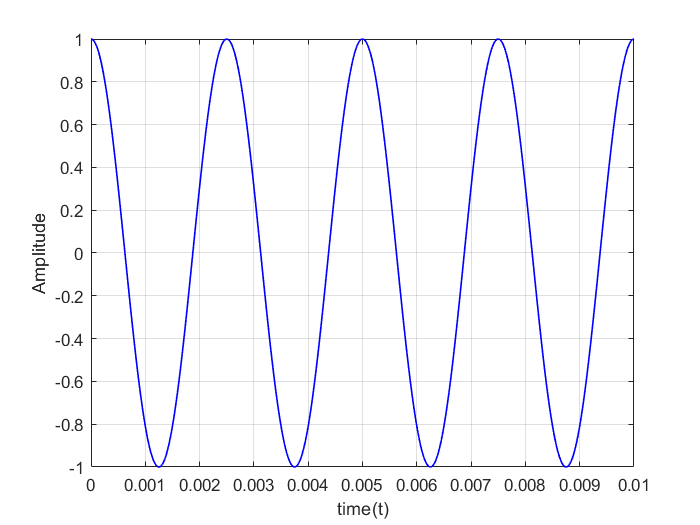

A = 1;          % Amplitude
f = 400;        % Frequency
time = 10e-3;   % Time limit
t = linspace(0,time,1000);
y_t = A*cos(2*pi*f*t); % Input signal
plot(t,y_t,'Color','b','LineStyle','-','LineWidth',1)
grid on; xlabel('time(t)'); ylabel('Amplitude')

## **Q3 Code Snippet**

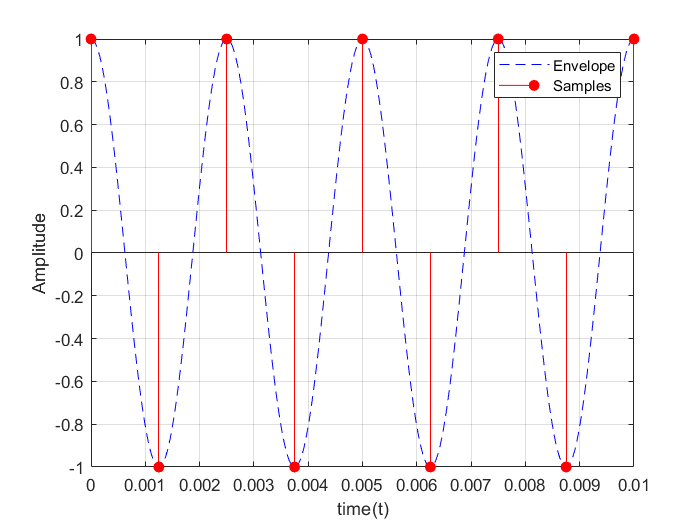

fnq = 2*f;                          % Nyquist sampling frequency
delta_t = 1/fnq;                    % Time duration between two samples
sample_at = 0:delta_t:time;         % Sampling moments
samples = A*cos(2*pi*f*sample_at);  % Sampled signal
plot(t,y_t, '--', 'Color','b');     % plotting the envelope
hold on
stem(sample_at,samples,'filled', 'r');% plotting the sampled signal
legend("Envelope","Samples");legend('show')
grid on; xlabel('time(t)'); ylabel('Amplitude')
hold off

## **Q4 Code Snippet**

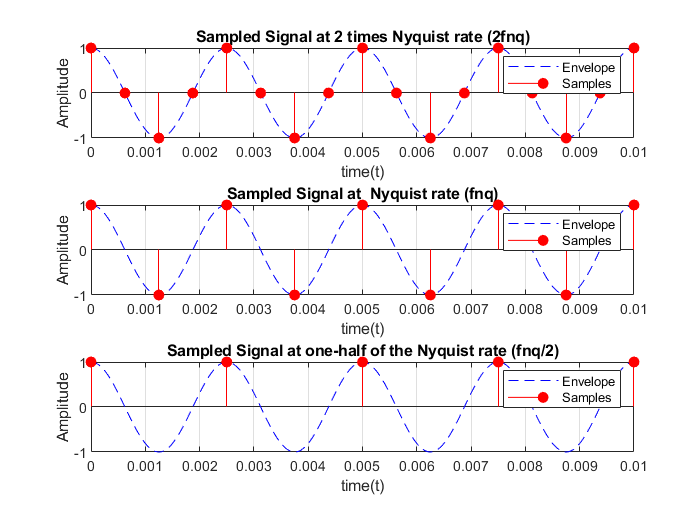

% Sampled Signal at 2 times Nyquist rate (2fnq)
subplot(3,1,1)
delta_t_2fnq = 1/(2*fnq);          % Time duration between two samples
sample_at = 0:delta_t_2fnq:time;   % Sampling moments
samples = A*cos(2*pi*f*sample_at); % Sampled signal
plot(t,y_t, '--', 'Color','b');    % plotting the envelope
hold on
stem(sample_at,samples,'filled', 'r'); % plotting the sampled signal
legend("Envelope","Samples");legend('show')
title("Sampled Signal at 2 times Nyquist rate (2fnq)")
grid on; xlabel('time(t)'); ylabel('Amplitude')
hold off

% Sampled Signal at  Nyquist rate (fnq)
subplot(3,1,2)
delta_t_1fnq = 1/(1*fnq);          % Time duration between two samples
sample_at = 0:delta_t_1fnq:time;   % Sampling moments
samples = A*cos(2*pi*f*sample_at); % Sampled signal
plot(t,y_t, '--', 'Color','b');    % plotting the envelope
hold on
stem(sample_at,samples,'filled', 'r'); % plotting the sampled signal
legend("Envelope","Samples");legend('show')
title("Sampled Signal at  Nyquist rate (fnq)")
grid on; xlabel('time(t)'); ylabel('Amplitude')
hold off

% Sampled Signal at one-half of the Nyquist rate (fnq/2)
subplot(3,1,3)
delta_t_halffnq = 1/(0.5*fnq);      % Time duration between two samples
sample_at = 0:delta_t_halffnq:time; % Sampling moments
samples = A*cos(2*pi*f*sample_at);  % Sampled signal
plot(t,y_t, '--', 'Color','b');     % plotting the envelope
hold on
stem(sample_at,samples,'filled', 'r'); % plotting the sampled signal
legend("Envelope","Samples");legend('show')
title("Sampled Signal at one-half of the Nyquist rate (fnq/2)")
grid on; xlabel('time(t)'); ylabel('Amplitude')
hold off

## **Q7 Code Snippet**

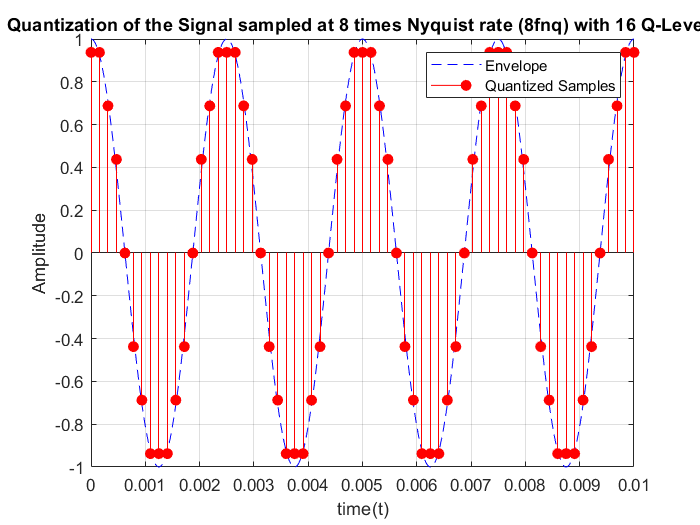

figure;
delta_t_8fnq = 1/(8*fnq);         % Time duration between two samples
sample_at = 0:delta_t_8fnq:time;  % Sampling moments
samples = A*cos(2*pi*f*sample_at);% Sampled signal
plot(t,y_t, '--', 'Color','b');   % plotting the envelope
hold on
% Quantization the sampled signal using the created function
qlevels = 16;
quantized_samples = zeros(1,length(samples));
for sample = 1: length(samples)
    quantized_samples(sample) = quantizeSample(round(samples(sample),5), qlevels,A);
end

%% Uncomment this part to plot the sampled signal
% stem(sample_at,samples, 'filled', 'r');
% legend("Envelope","Samples");legend('show')
% title("Sampled Signal at 8 times Nyquist rate (8fnq)")

% plotting the quantized signal
stem(sample_at,quantized_samples, 'filled', 'r');
legend("Envelope","Quantized Samples");legend('show')
title("Quantization of the Signal sampled at 8 times Nyquist rate (8fnq) with 16 Q-Levels")
grid on; xlabel('time(t)'); ylabel('Amplitude')
hold off

## **Q8 Code Snippet**

**Quantized with 2L = 32 Quantization Levels**

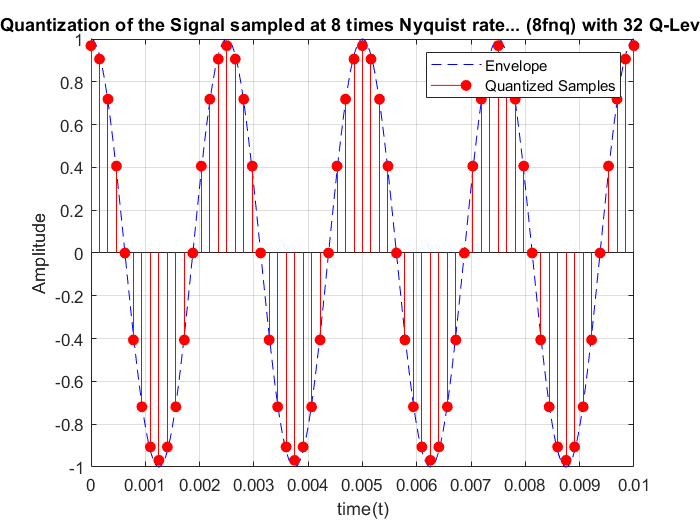

figure;
plot(t,y_t, '--', 'Color','b');        % plotting the envelope
hold on
% Quantization the sampled signal using the created function
qlevels = 32;
quantized_samples = zeros(1,length(samples));
for sample = 1: length(samples)
    quantized_samples(sample) = quantizeSample(round(samples(sample),5), qlevels,A);
end
% plotting the quantized signal
stem(sample_at,quantized_samples, 'filled', 'r');
legend("Envelope","Quantized Samples");legend('show')
title("Quantization of the Signal sampled at 8 times Nyquist rate..." + ...
    " (8fnq) with 32 Q-Levels")
grid on; xlabel('time(t)'); ylabel('Amplitude')
hold off

**Quantized with L/2 = 8 Quantization Levels**

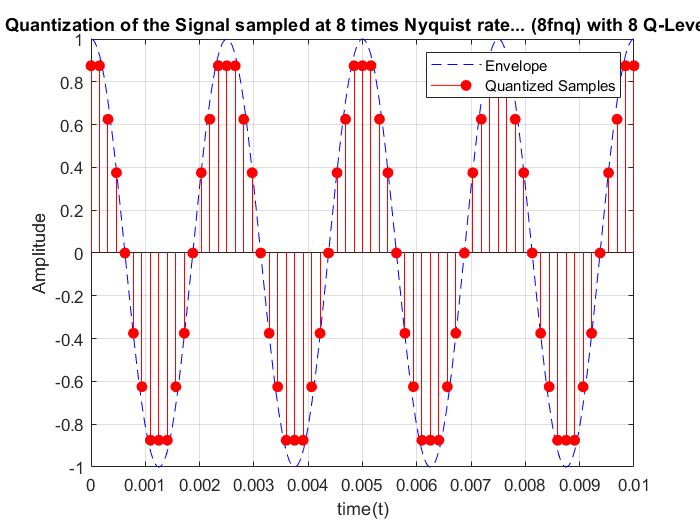

figure;
plot(t,y_t, '--', 'Color','b');        % plotting the envelope
hold on
% Quantization the sampled signal using the created function
qlevels = 8;
quantized_samples = zeros(1,length(samples));
for sample = 1: length(samples)
    quantized_samples(sample) = quantizeSample(round(samples(sample),5), qlevels,A);
end
% plotting the quantized signal
stem(sample_at,quantized_samples, 'filled', 'r');
legend("Envelope","Quantized Samples");legend('show')
title("Quantization of the Signal sampled at 8 times Nyquist rate..." + ...
    " (8fnq) with 8 Q-Levels")
grid on; xlabel('time(t)'); ylabel('Amplitude')
hold off

# **Function definition for Quantization**

function quantized = quantizeSample(sample, qlevels,maxamp)

DeltaV = 2*maxamp/qlevels;     % Quantiation interval size
if sample == maxamp                     % Positive extreme
    quantized = sample - DeltaV/2;
    return
elseif sample == -1*maxamp              % Negative extreme
    quantized = sample + DeltaV/2;
    return
elseif abs(sample) == 0 % zero means no sample to quantize
    quantized = 0;
    return
    % If the sample value does not belongs to any of the above cases
else
    % Iterate through Quantization levels
    for level = -1*maxamp:DeltaV:maxamp
        if level == sample % If a sample is exactly equal to a q-level
            if sample <0
                % Negative samples are quantized towards negative infinity
                quantized = level - DeltaV/2;
                return
            else
                % Positive samples are quantized towards positive infinity
                quantized = level + DeltaV/2;
                return
            end
        elseif level > sample        % If a sample lies between two levels
            quantized = level -DeltaV/2;
            return
        end
    end
end
end